clear all;
close all;
clc;


## SYMBOLIC SIGNAL REPRESENTATION

% continuous time and functions
syms tc fc;
fc = sin(tc)

$$fc = \sin\left(\mathrm{tc}\right)$$


% obtain symbolic derivative
dfcdt = diff(fc)

$$dfcdt = \cos\left(\mathrm{tc}\right)$$

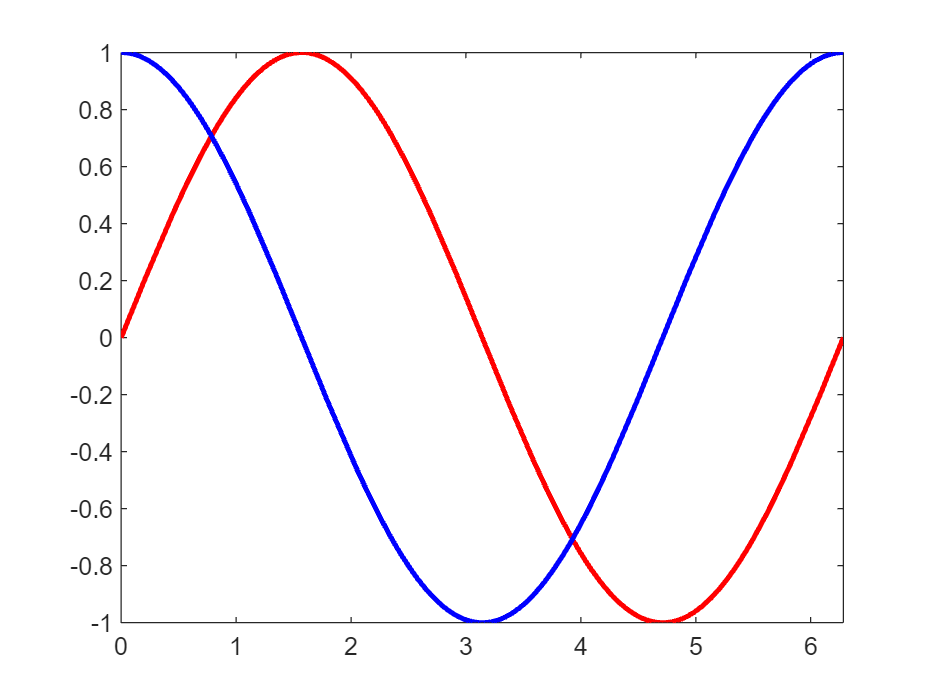


figure(2)
fplot(tc,fc,[0,2*pi],'-r','LineWidth',2)
hold on
fplot(tc,dfcdt,[0,2*pi],'-b','LineWidth',2)

## DISCRETE SIGNAL REPRESENTATION

% number of points
N = 41;
% discrete time
td = linspace(0, 2*pi, N);
% the discrete function
fd = sin(td);

% sampling frequency
timestep = td(2)-td(1);
fs = 1/(timestep);

% obtain discrete derivative
dfddt = gradient(fd,timestep)

dfddt =     0.9959    0.9836    0.9472    0.8873    0.8057    0.7042    0.5854    0.4521    0.3077    0.1558         0   -0.1558   -0.3077   -0.4521   -0.5854   -0.7042   -0.8057   -0.8873   -0.9472   -0.9836   -0.9959   -0.9836   -0.9472   -0.8873   -0.8057   -0.7042   -0.5854   -0.4521   -0.3077   -0.1558   -0.0000    0.1558    0.3077    0.4521    0.5854    0.7042    0.8057    0.8873    0.9472    0.9836    0.9959



disp(['the sampling frequency is:    ' num2str(fs)])

the sampling frequency is:    6.3662


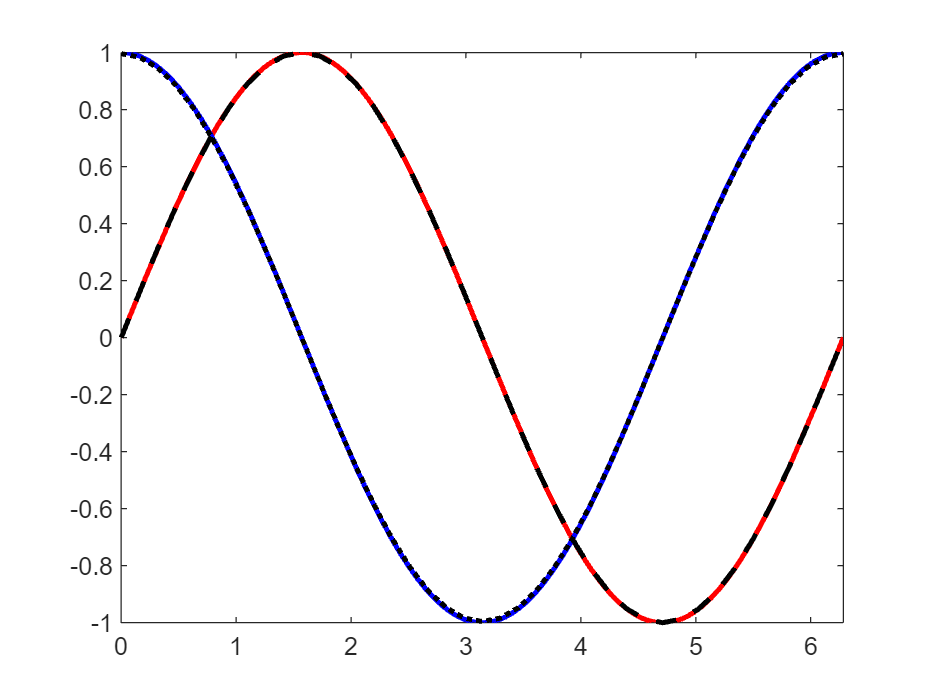


% plot solution
plot(td,fd,'--k','LineWidth',2)
plot(td,dfddt,':k','LineWidth',2)